### xExtracting the SAM-recognized trees

By loading the output labeled matrix from the SAM classification and using it as a mask for the original hyperspectral image

load("testGT.mat")
load("wavelengths.mat")
hcube = hypercube("CROP1_47.tiff",wavelength);
[rows, cols, ~] = size(hcube.DataCube);

Masquerade taking all the pixels with label 2 (=Tree)

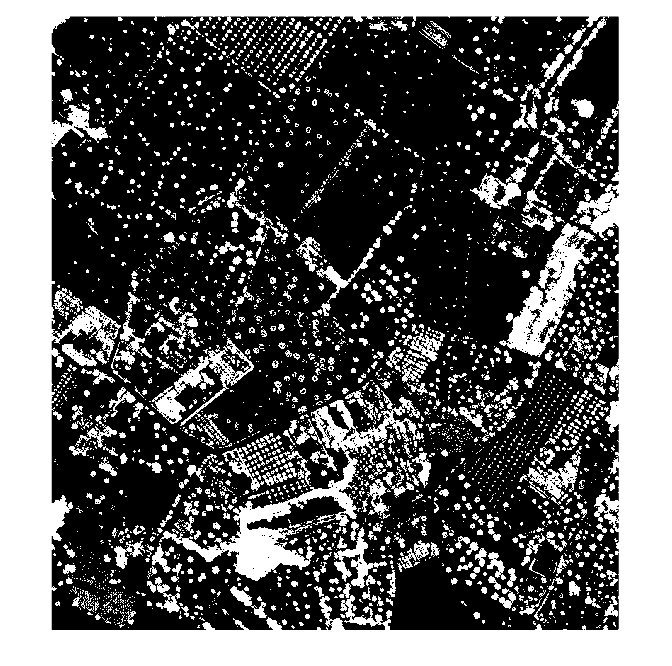

tree_mask = reshape(classMap==2, [rows, cols]);
figure
imshow(tree_mask,[])

So we apply the mask to the hypercube, by reshaping the matrix

sCube=size(hcube.DataCube);
tree_points=reshape(hcube.DataCube,[],sCube(3));
tree_points(~tree_mask,:)=0;
tree_points=reshape(tree_points,sCube);


So we create the new hypercube with only the previously classificated as tree-points valued, and colorize it.

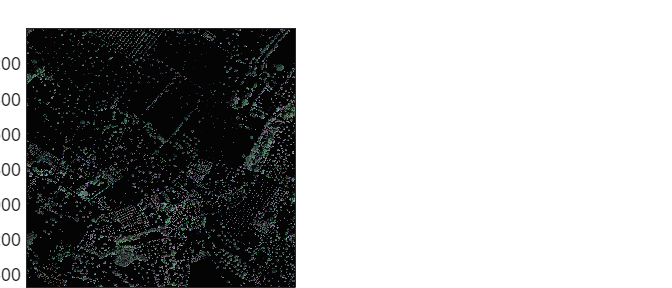

newhcube=hypercube(tree_points,wavelength);
fig = figure('Position',[0 0 700 300]);
axes1 = axes('Parent',fig,'Position',[0.04 0 0.4 0.9]);
rgbImg= colorize(newhcube,"Method","rgb","ContrastStretching",true);
imagesc(rgbImg,'Parent',axes1);

Now, that's the binary mask given for this task, compared with the SAM-generated one

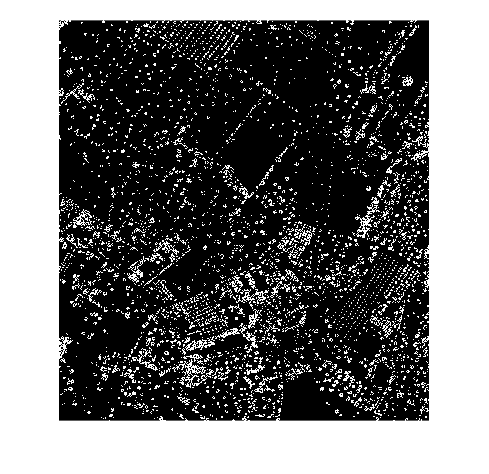

seg_crop=imread("tree_distinguish/source_cropping/Seg_Crop1.tif");
%diff_trees=seg_crop-tree_mask;
%imshow(diff_trees,[])
imshow(seg_crop,[])

We can see that the given mask is more precise than our generated one, so let's create the hypercube with this new mask

sCube=size(hcube.DataCube);
tree_points=reshape(hcube.DataCube,[],sCube(3));
tree_points(~seg_crop,:)=0;
tree_points=reshape(tree_points,sCube);

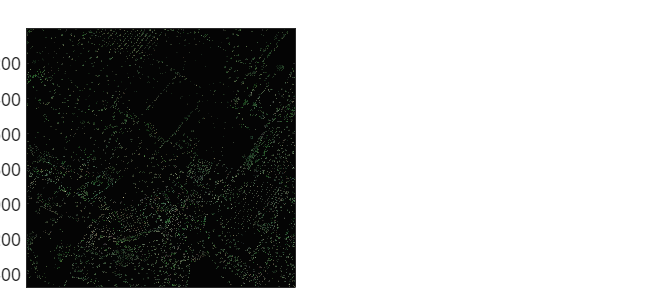

newhcube=hypercube(tree_points,wavelength);
fig = figure('Position',[0 0 700 300]);
axes1 = axes('Parent',fig,'Position',[0.04 0 0.4 0.9]);
set(axes1, 'YTick', []);
rgbImg= colorize(newhcube,"Method","rgb","ContrastStretching",true);
imagesc(rgbImg,'Parent',axes1);

enviwrite(newhcube,'tree_distinguish/source_cropping/crop_trees')